# MVP CPR Frequency Analysis

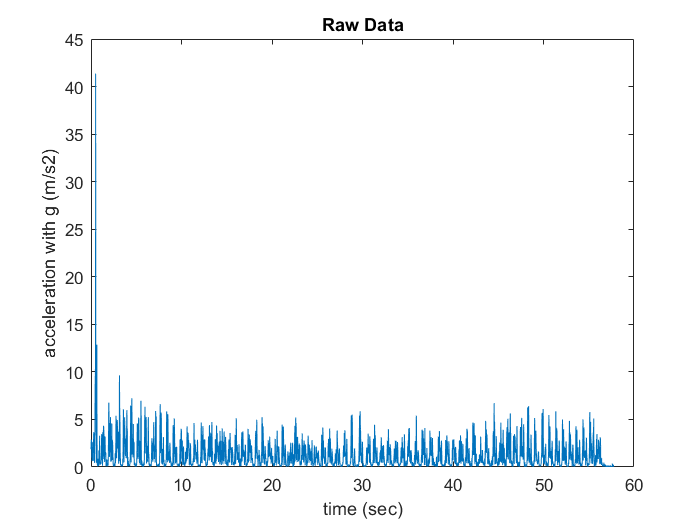

% import first and last column of xls data as double
% this is a data of me preforming CPR on my leg: )
clear
[numbers, strings, raw] = xlsread("coach_test.xls");
accel = numbers(:,5);
time = numbers(:,1);

% plot time domain data
figure(1)
plot(time,accel)
title("Raw Data")
xlabel("time (sec)")
ylabel("acceleration with g (m/s2)")

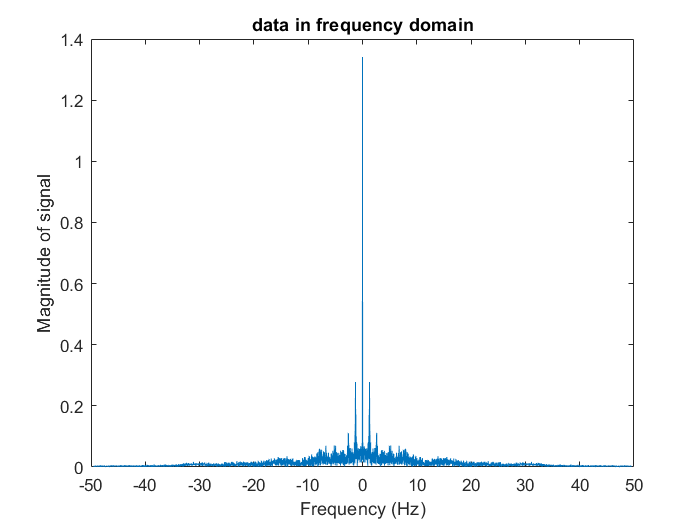

amp =     1.3409
    0.2779
    0.2779


freq = 1.2954



% total number of samples
N = length(time); 
% sampling rate: 
Fs = round(N/time(end)); % # of samples per time(sec)

% perform DFT to calculate overall CPR frequency
% amp: max amplitude
% freq: dominant frequency (Hz)
[amp,freq] = make_freq_plot_max(accel,Fs)

freq_bpm = freq * 60; % convert from Hz to bpm

% data segmentation to calculate consistency
seg_time = 5;
i_start = 1;
seg_number = 1;
[~, i_length] = min(abs(time - seg_time));
i_end = i_start + i_length;
overlap_i = 100

overlap_i = 100

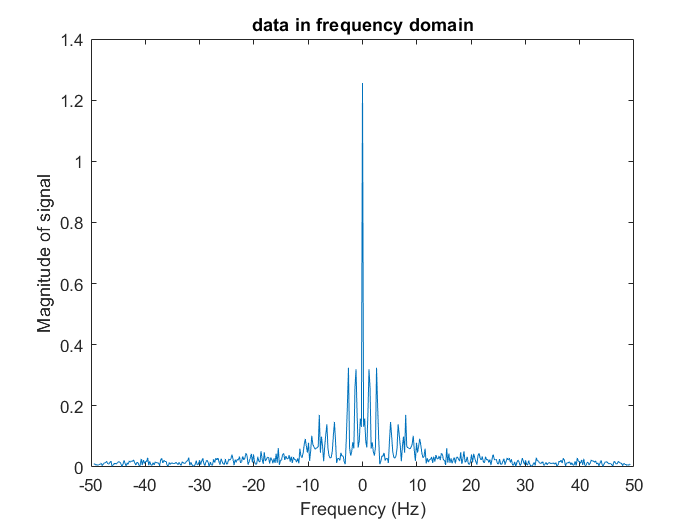


while i_end <= length(time)
time_list(:,seg_number) = time(i_start:i_end);
data_list(:,seg_number) = accel(i_start:i_end);
i_start = i_end - overlap_i;
i_end = i_start + i_length;
seg_number = seg_number + 1;
end 

amp_list = [];
freq_list = [];
for col = 1: size(time_list,2)
    data_part = data_list(:,col);
    [amp_part,freq_part] = make_freq_plot_max(data_part,Fs);
%     disp("amp: " + amp)
%     disp("freq: " + freq)
    % freq prob shouldn't use max
    amp_list(end+1) = max(amp_part);
    freq_list(end+1:end + length(freq_part)) = freq_part;
    amp_consistency = std(amp_list);
    freq_consistency = std(freq_list);  
end


if freq_consistency < 0.3
    disp("good consistency:)")
    consistency_coeff = 1;
elseif freq_consistency <1.5
    disp("improve your consistency to do better!")
    consistency_coeff = 0.8;
else
    disp("bad consistency: (")
    consistency_coeff = 0.6;
    isoutlier(freq_list)
end

improve your consistency to do better!



% calculate score and display
if freq_bpm <= 120 && freq_bpm >= 100
    score = 100;
    disp("Good job!")
elseif freq_bpm > 120
    score = 100 - (freq_bpm - 120) / 120 * 100;
    disp("That was too fast!")
elseif freq_bpm < 100
    score = 100 - (100 - freq_bpm) / 100 * 100;
    disp("That was too slow!")
end 

That was too slow!



%round up to 3 sig-figs
score = round(score,1);
score = consistency_coeff * score;
disp("Your score is: " + score)

Your score is: 62.16


if score < 30
    disp("Try again!")
end